### Global Variables

prec = 100;
digits(prec);

N_max = 10;
x = 20.0;

x_max = 20.0;
x_min = -20.0;
x_size = 100;

X = linspace(x_max,x_min,x_size);
x_axi_plot = linspace(0,N_max,N_max+1);

wavefunction_MATLAB_1_1_list = zeros(1,N_max+1);
wavefunction_Fast_Wave_sfsp_2_list = zeros(1,N_max+1);

wavefunction_MATLAB_2_2_list = zeros(1,N_max+1);
wavefunction_Fast_Wave_sfmp_2_list = zeros(1,N_max+1);

wavefunction_MATLAB_3_list = zeros(1,N_max+1);
wavefunction_Fast_Wave_mfsp_list = zeros(1,N_max+1);

wavefunction_MATLAB_4_list = zeros(1,N_max+1);
wavefunction_Fast_Wave_mfmp_list = zeros(1,N_max+1);

left = 0.08; 
bottom = 0.45; 
width = 0.4; 
height = 0.4;

### Tests

#### `Single Fock and Single Position speed test `

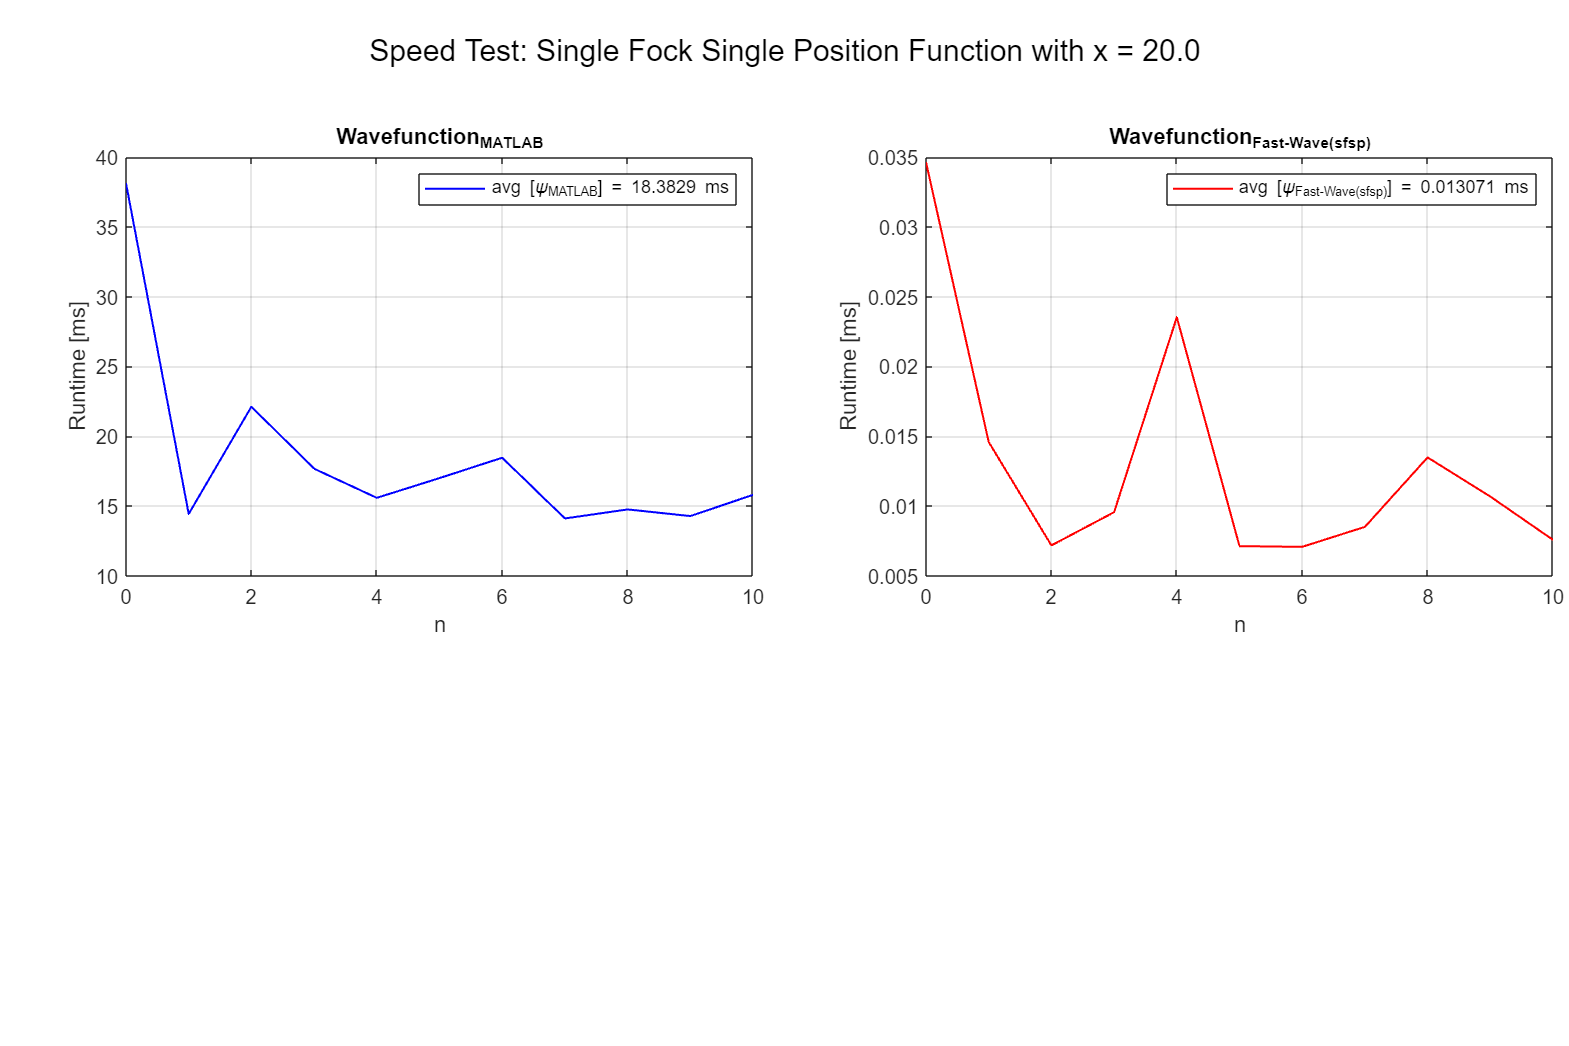

import py.fast_wave.wavefunction_cython.psi_n_single_fock_single_position

for n = 0:N_max
    f1 = @()(wavefunction_MATLAB_1(n,x,prec)); 
    f2 = @()(psi_n_single_fock_single_position(uint64(n), x));
    exec_time_1 = timeit(f1) * 1000;
    exec_time_2 = timeit(f2) * 1000;
    wavefunction_MATLAB_1_1_list(n+1) = exec_time_1;
    wavefunction_Fast_Wave_sfsp_2_list(n+1) = exec_time_2;
end

figure('Position', [100, 100, 1200, 800]);
subplot('Position', [left bottom width height]);
plot(x_axi_plot, wavefunction_MATLAB_1_1_list, 'b-','LineWidth', 1); 
grid on;
xlabel('n');
ylabel('Runtime [ms]');
legend(sprintf('avg [\\psi_{MATLAB}] = '+ string(mean(wavefunction_MATLAB_1_1_list))+' ms'));
title('Wavefunction_{MATLAB}');

left = 0.59;
subplot('Position', [left bottom width height]);
plot(x_axi_plot, wavefunction_Fast_Wave_sfsp_2_list,'r-','LineWidth', 1); 
grid on;
xlabel('n');
ylabel('Runtime [ms]');
title('Wavefunction_{Fast-Wave(sfsp)}');
sgtitle('Speed Test: Single Fock Single Position Function with x = 20.0');
legend(sprintf('avg [\\psi_{Fast-Wave(sfsp)}] = '+ string(mean(wavefunction_Fast_Wave_sfsp_2_list))+' ms'));

#### `Single Fock and Multiple Position speed test `

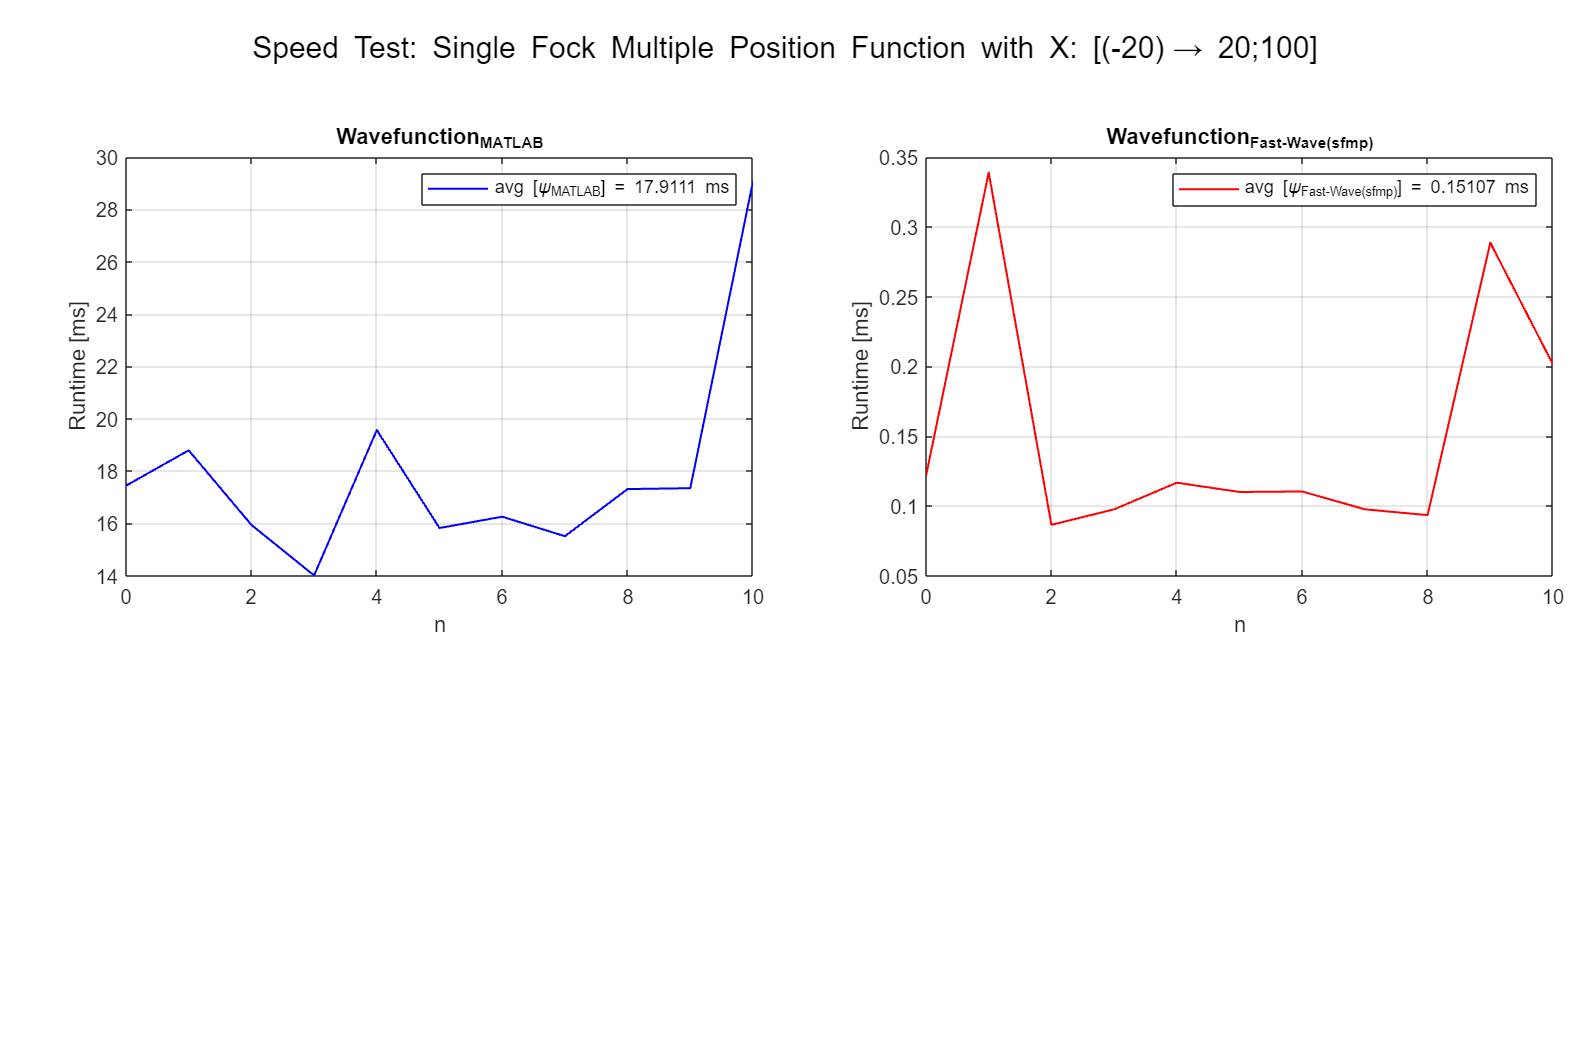

import py.fast_wave.wavefunction_cython.psi_n_single_fock_multiple_position

left = 0.08; 

for n = 0:N_max
    f1 = @()(wavefunction_MATLAB_1(n,x,prec)); 
    f2 = @()(psi_n_single_fock_multiple_position(uint64(n), py.numpy.array(X)));
    exec_time_1 = timeit(f1) * 1000;
    exec_time_2 = timeit(f2) * 1000;
    wavefunction_MATLAB_2_2_list(n+1) = exec_time_1;
    wavefunction_Fast_Wave_sfmp_2_list(n+1) = exec_time_2;
end

figure('Position', [50, 50, 1200, 800]);
subplot('Position', [left bottom width height]);
plot(x_axi_plot, wavefunction_MATLAB_2_2_list, 'b-','LineWidth', 1); 
grid on;
xlabel('n');
ylabel('Runtime [ms]');
legend(sprintf('avg [\\psi_{MATLAB}] = '+ string(mean(wavefunction_MATLAB_2_2_list))+' ms'));
title('Wavefunction_{MATLAB}');

left = 0.59;
subplot('Position', [left bottom width height]);
plot(x_axi_plot, wavefunction_Fast_Wave_sfmp_2_list,'r-','LineWidth', 1); 
grid on;
xlabel('n');
ylabel('Runtime [ms]');
title('Wavefunction_{Fast-Wave(sfmp)}');
sgtitle(sprintf('Speed Test: Single Fock Multiple Position Function with X: [(-20)\\rightarrow 20;100]'));
legend(sprintf('avg [\\psi_{Fast-Wave(sfmp)}] = '+ string(mean(wavefunction_Fast_Wave_sfmp_2_list))+' ms')); 

#### `Multiple Fock and Single Position speed test`

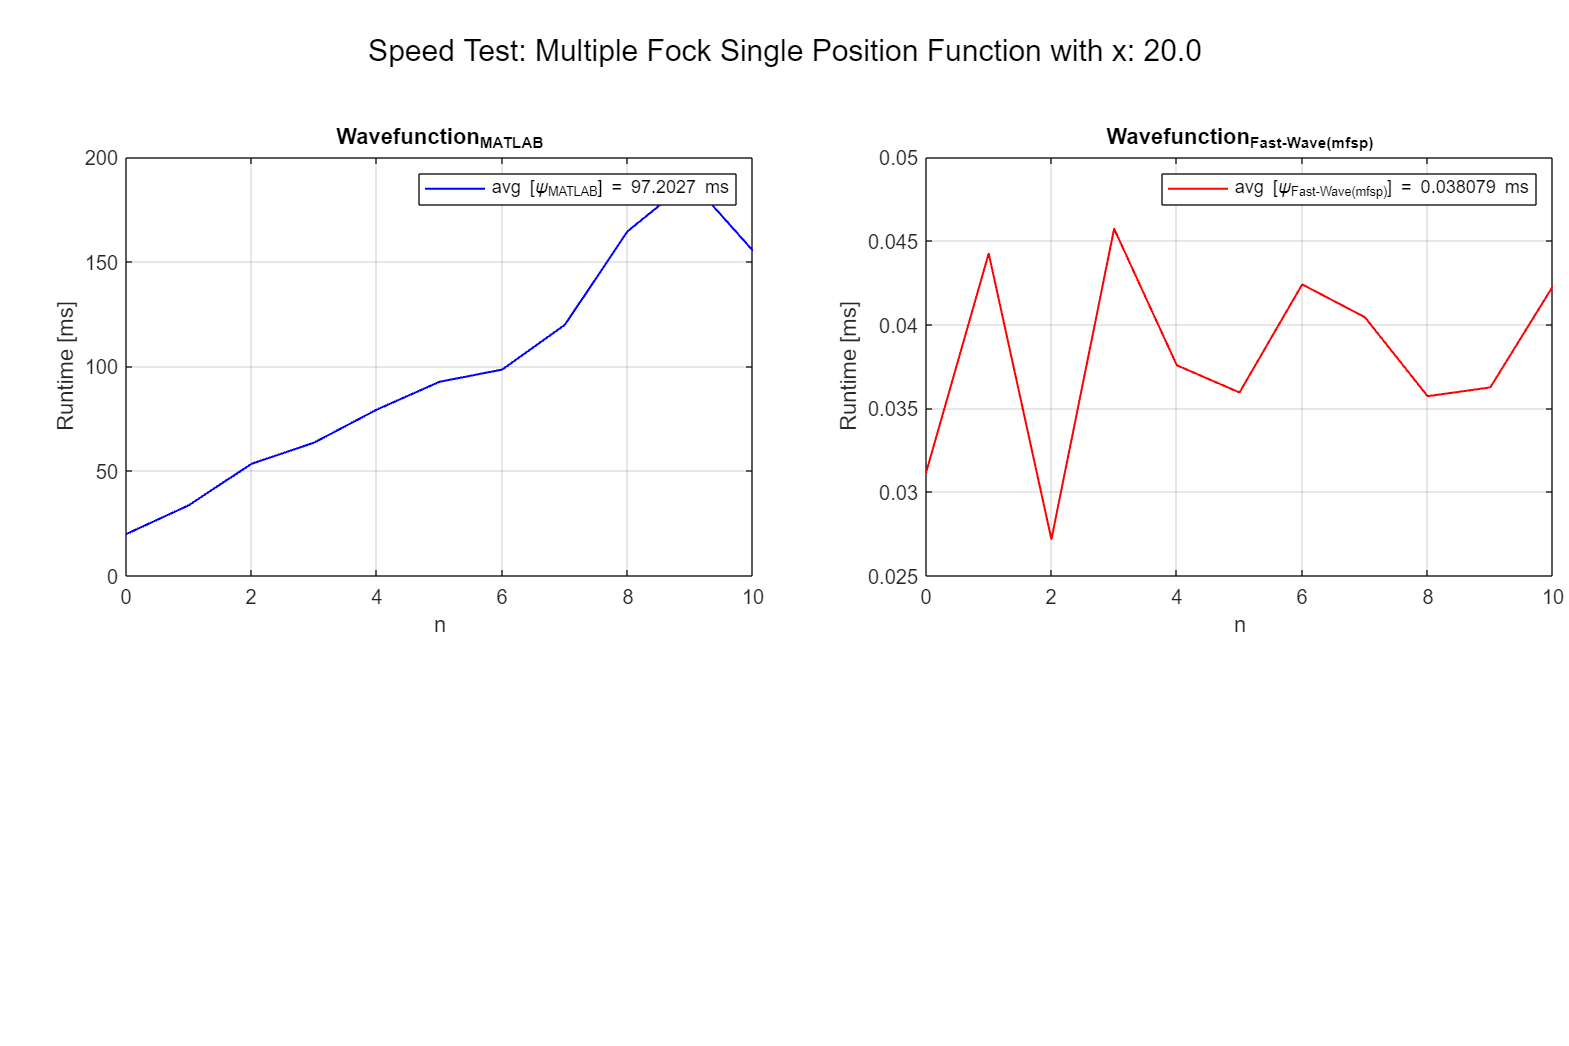

import py.fast_wave.wavefunction_cython.psi_n_multiple_fock_single_position

left = 0.08; 

for n = 0:N_max
    f1 = @()(wavefunction_MATLAB_3(n,x,prec)); 
    f2 = @()(psi_n_multiple_fock_single_position(uint64(n),x));
    exec_time_1 = timeit(f1) * 1000;
    exec_time_2 = timeit(f2) * 1000;
    wavefunction_MATLAB_3_list(n+1) = exec_time_1;
    wavefunction_Fast_Wave_mfsp_list(n+1) = exec_time_2;
end

figure('Position', [50, 50, 1200, 800]);
subplot('Position', [left bottom width height]);
plot(x_axi_plot, wavefunction_MATLAB_3_list, 'b-','LineWidth', 1); 
grid on;
xlabel('n');
ylabel('Runtime [ms]');
legend(sprintf('avg [\\psi_{MATLAB}] = '+ string(mean(wavefunction_MATLAB_3_list))+' ms'));
title('Wavefunction_{MATLAB}');

left = 0.59;
subplot('Position', [left bottom width height]);
plot(x_axi_plot, wavefunction_Fast_Wave_mfsp_list,'r-','LineWidth', 1); 
grid on;
xlabel('n');
ylabel('Runtime [ms]');
title('Wavefunction_{Fast-Wave(mfsp)}');
sgtitle(sprintf('Speed Test: Multiple Fock Single Position Function with x: 20.0'));
legend(sprintf('avg [\\psi_{Fast-Wave(mfsp)}] = '+ string(mean(wavefunction_Fast_Wave_mfsp_list))+' ms')); 

#### `Multiple Fock and Multiple Position speed test`

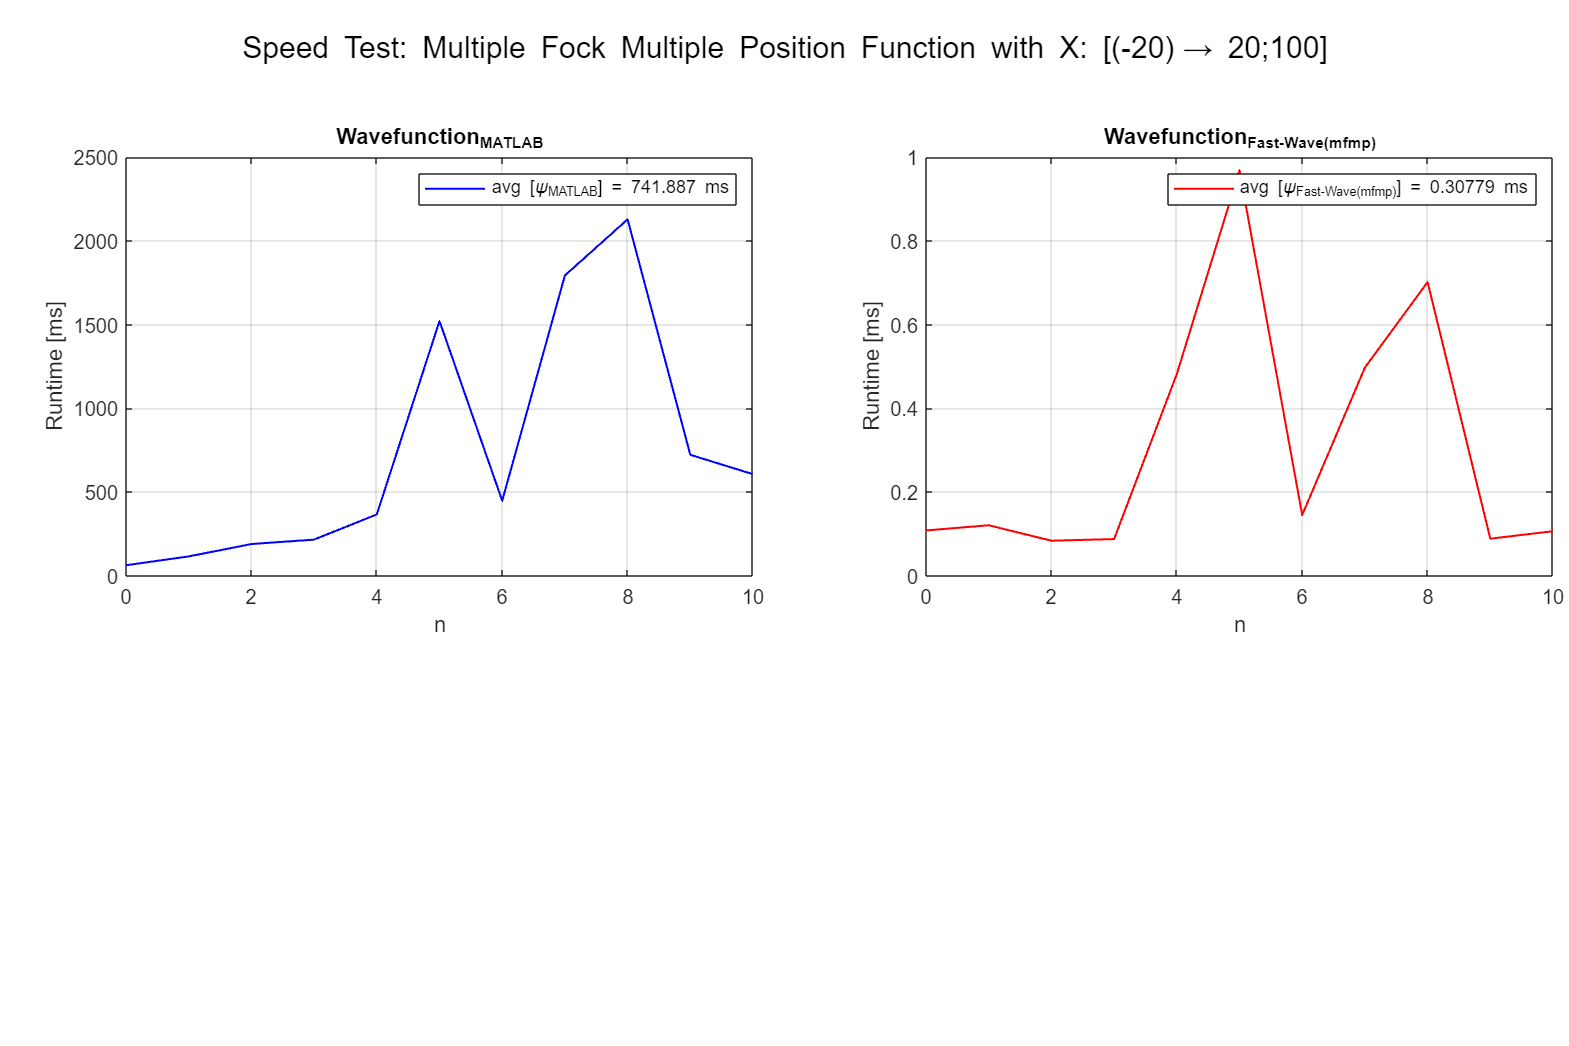

import py.fast_wave.wavefunction_cython.psi_n_multiple_fock_multiple_position

left = 0.08; 

for n = 0:N_max
    f1 = @()(wavefunction_MATLAB_4(n,X,prec)); 
    f2 = @()(psi_n_multiple_fock_multiple_position(uint64(n),py.numpy.array(X)));
    exec_time_1 = timeit(f1) * 1000;
    exec_time_2 = timeit(f2) * 1000;
    wavefunction_MATLAB_4_list(n+1) = exec_time_1;
    wavefunction_Fast_Wave_mfmp_list(n+1) = exec_time_2;
end

figure('Position', [50, 50, 1200, 800]);
subplot('Position', [left bottom width height]);
plot(x_axi_plot, wavefunction_MATLAB_4_list, 'b-','LineWidth', 1); 
grid on;
xlabel('n');
ylabel('Runtime [ms]');
legend(sprintf('avg [\\psi_{MATLAB}] = '+ string(mean(wavefunction_MATLAB_4_list))+' ms'));
title('Wavefunction_{MATLAB}');

left = 0.59;
subplot('Position', [left bottom width height]);
plot(x_axi_plot, wavefunction_Fast_Wave_mfmp_list,'r-','LineWidth', 1); 
grid on;
xlabel('n');
ylabel('Runtime [ms]');
title('Wavefunction_{Fast-Wave(mfmp)}');
sgtitle(sprintf('Speed Test: Multiple Fock Multiple Position Function with X: [(-20)\\rightarrow 20;100]'));
legend(sprintf('avg [\\psi_{Fast-Wave(mfmp)}] = '+ string(mean(wavefunction_Fast_Wave_mfmp_list))+' ms')); 